Parameters

clear();

caseno = 4;
shouldSave = false;

% Parameters
m = 3; % Number of suppliers
n = 2; % Number of consumers

% Time span
time = 3;
t_span = [0, time];

% Vectors
tau_g = [0.1, 0.3, 0.2];
a_g = [0.3, 0.5, 0.2];
b_g = [1 2 1];

tau_d = [0.2, 0.25];
a_d = [-0.5, -0.6];
b_d = [10, 8];

% Scalars
mu = 0.5;
theta_ = 5.9;
eta = 0.5;
theta = 6.4;

% Vectors alpha and beta
alpha = [0, 1/eta];
beta = [-1/(mu*eta), -theta/(mu*eta)];

% Define time decomposition parameters
N = 1000;
td_span = linspace(0, time, N);

% Initial conditions
Pg_ic = [5 3 2]; % Зменшене початкове виробництво
Pd_ic = [7 5]; % Збільшений початковий попит
x10 = 1;
x20 = 7;
initial_conditions = [Pg_ic Pd_ic x10 x20];


## Base Model

Solve ODE

[t, X] = ode45(@(t, X) basic_system_of_equations(t, X, tau_g, a_g, b_g, tau_d, a_d, b_d, alpha, beta), t_span, initial_conditions);

% Extract solutions
Pg_extracted = X(:, 1:m);
Pd_extracted = X(:, m + 1:m + n);
pi_extracted = X(:, m + n + 1);

% Compute Pg and Pd
Pg = sum(Pg_extracted , 2);
Pd = sum(Pd_extracted , 2);
Pi = pi_extracted;

Plotting

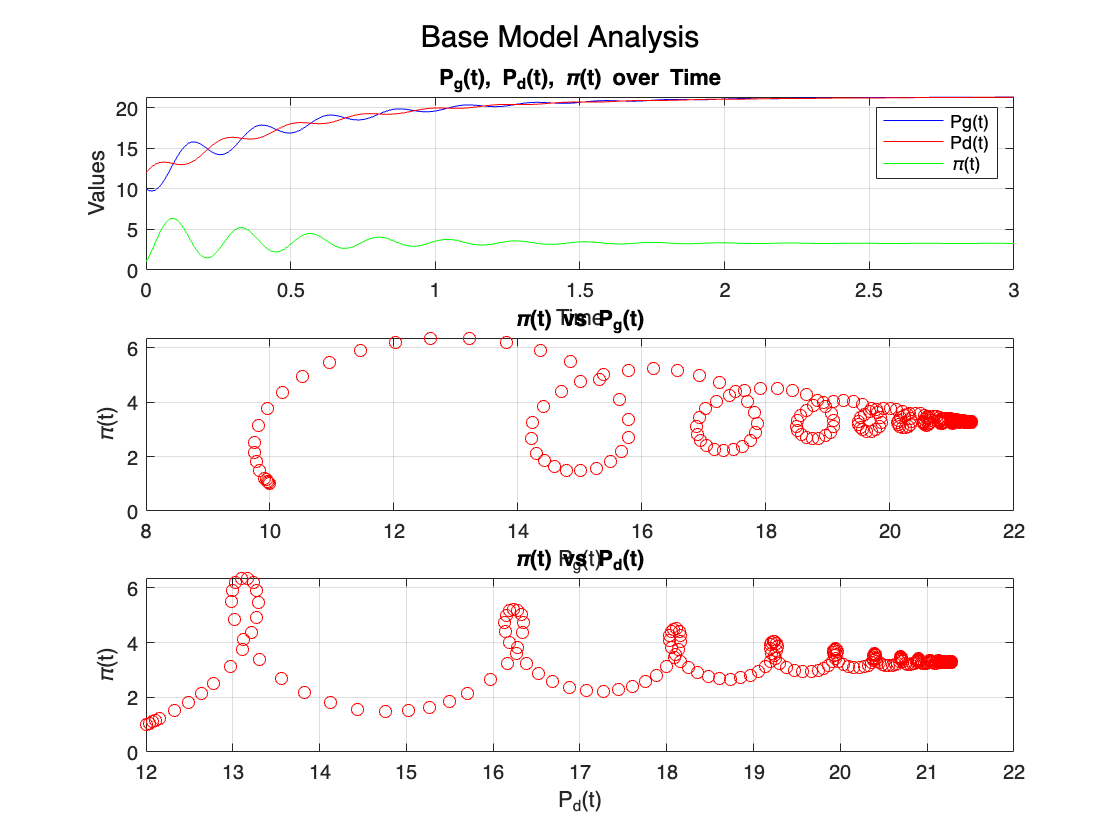

a = figure;

subplot(3, 1, 1);
plot(t, Pg, 'b', 'DisplayName', 'Pg(t)');
hold on;
plot(t, Pd, 'r', 'DisplayName', 'Pd(t)');
plot(t, Pi, 'g', 'DisplayName', '\pi(t)');
xlabel('Time');
ylabel('Values');
legend;
title('P_g(t), P_d(t), \pi(t) over Time');
grid on;

subplot(3, 1, 2);
plot(Pg, Pi, 'ro');
xlabel('P_g(t)');
ylabel('\pi(t)');
title('\pi(t) vs P_g(t)');
grid on;

subplot(3, 1, 3);
plot(Pd, Pi, 'ro');
xlabel('P_d(t)');
ylabel('\pi(t)');
title('\pi(t) vs P_d(t)');
grid on;

sgtitle("Base Model Analysis");

saveFigureIfNeeded(shouldSave, caseno, 'base_analysis.png', a);

Figure not saved.


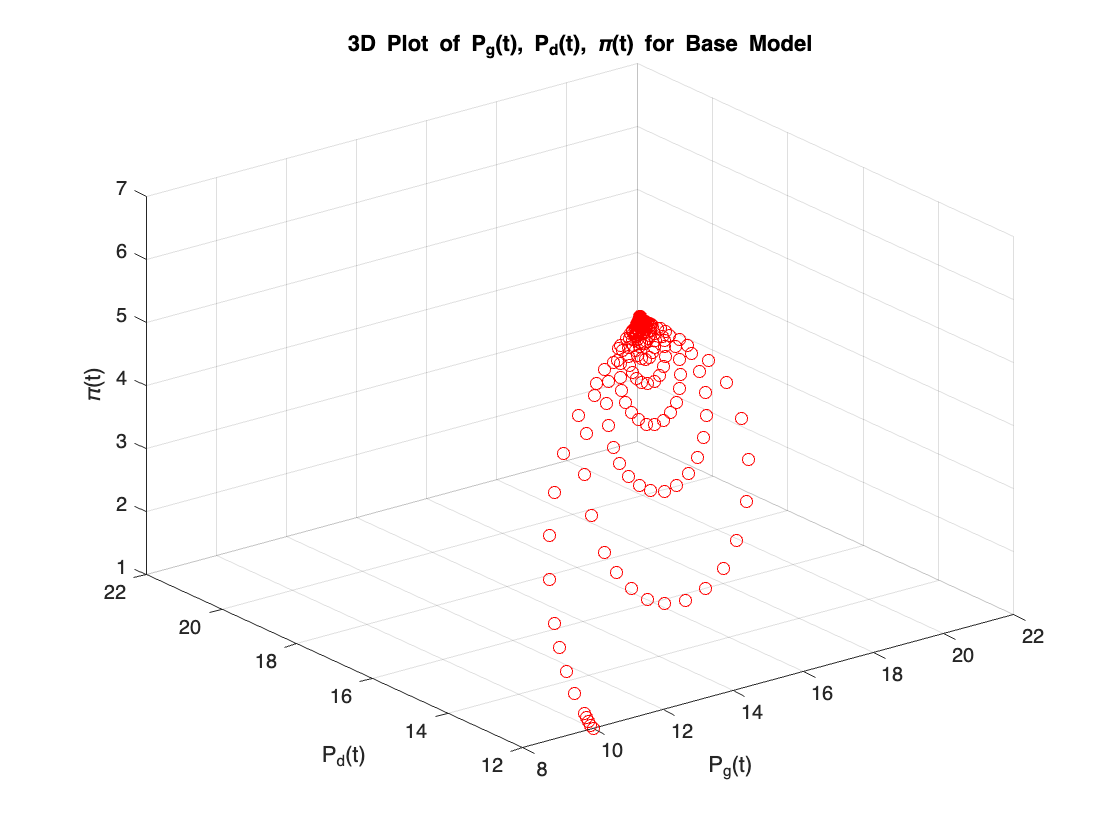


b = figure;
plot3(Pg, Pd, Pi, 'ro');
xlabel('P_g(t)');
ylabel('P_d(t)');
zlabel('\pi(t)');
title('3D Plot of P_g(t), P_d(t), \pi(t) for Base Model');
grid on;

saveFigureIfNeeded(shouldSave, caseno, '3d-base.png', b);

Figure not saved.


## Aggregated Model

Creating aggregated model parameters

% Define additional parameters and matrices
cm = ones(m, 1);
cn = -ones(n, 1);
T_g = diag(tau_g);
T_d = diag(tau_d);
A_g = diag(a_g);
A_d = diag(a_d);
B_g = diag(b_g);
B_d = diag(b_d);

% Compute intermediate variables
tau__g = cm' * inv(T_g) * cm; % 18.333
a__g = cm' * inv(T_g) * A_g * cm;  % 5.667
b__g = cm' * inv(T_g) * B_g * cm;  % 21.667
tau__d = cn' * inv(T_d) * cn; % 9
a__d = cn' * inv(T_d) * A_d * cn;  % -4.9
b__d = cn' * inv(T_d) * B_d * cn;  % 82

aggregated_initial_conditions = [sum(Pg_ic), sum(Pd_ic), x10, x20];

Solve ODE

% Solve the differential equations
[t, X] = ode45(@(t, X) aggregated_system_of_equations(t, X, tau__g, a__g, b__g, tau__d, a__d, b__d, alpha, beta), t_span, aggregated_initial_conditions);

% Extract solutions
Pg_ag = X(:, 1);
Pd_ag = X(:, 2);
dPi = X(:, 3);
Pi_ag = X(:, 4);

Plotting the results

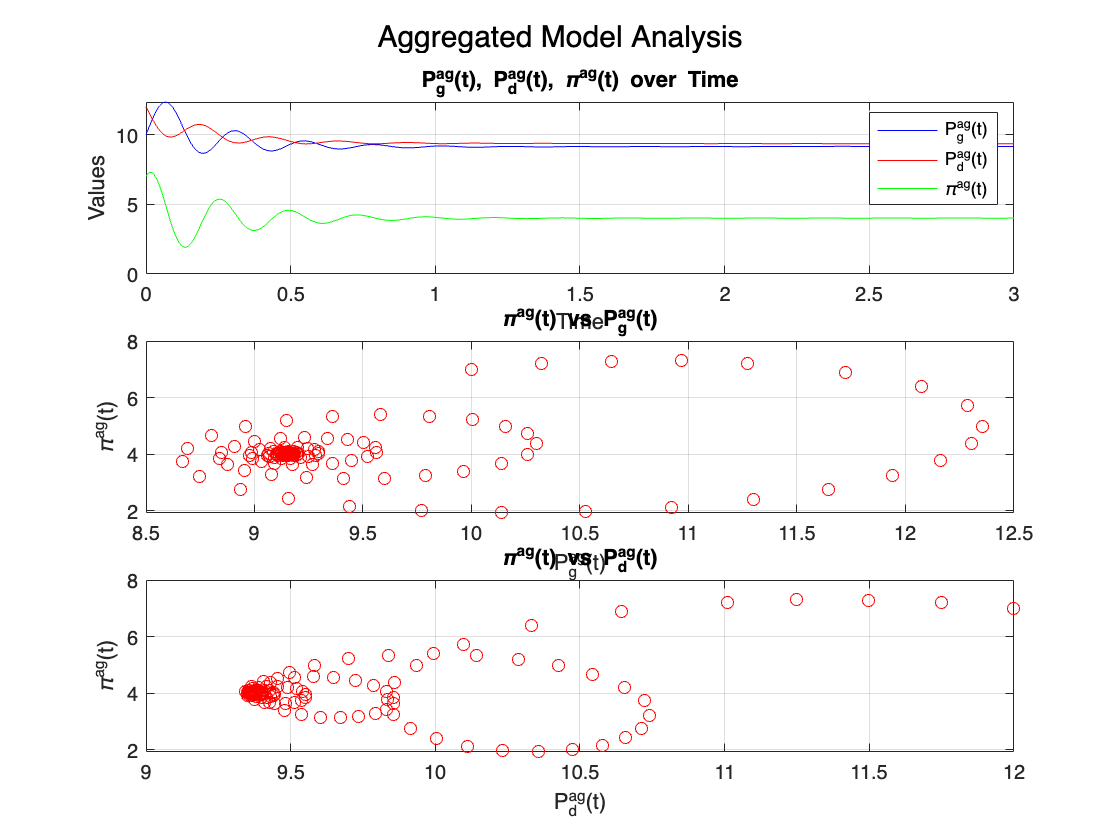

c = figure;

h1 = subplot(3, 1, 1);
plot(t, Pg_ag, 'b', 'DisplayName', 'Pg(t)');
hold on;
plot(t, Pd_ag, 'r', 'DisplayName', 'Pd(t)');
plot(t, Pi_ag, 'g', 'DisplayName', 'Pi(t)');
xlabel('Time');
ylabel('Values');
legend('P_g^{ag}(t)', 'P_d^{ag}(t)', '\pi^{ag}(t)');
title('P_g^{ag}(t), P_d^{ag}(t), \pi^{ag}(t) over Time');
grid on;

h2 = subplot(3, 1, 2);
plot(Pg_ag, Pi_ag, 'ro');
xlabel('P_g^{ag}(t)');
ylabel('\pi^{ag}(t)');
title('\pi^{ag}(t) vs P_g^{ag}(t)');
grid on;

h3 = subplot(3, 1, 3);
plot(Pd_ag, Pi_ag, 'ro');
xlabel('P_d^{ag}(t)');
ylabel('\pi^{ag}(t)');
title('\pi^{ag}(t) vs P_d^{ag}(t)');
grid on;

sgtitle('Aggregated Model Analysis');


saveFigureIfNeeded(shouldSave, caseno, 'aggregated_analysis.png', c);

Figure not saved.


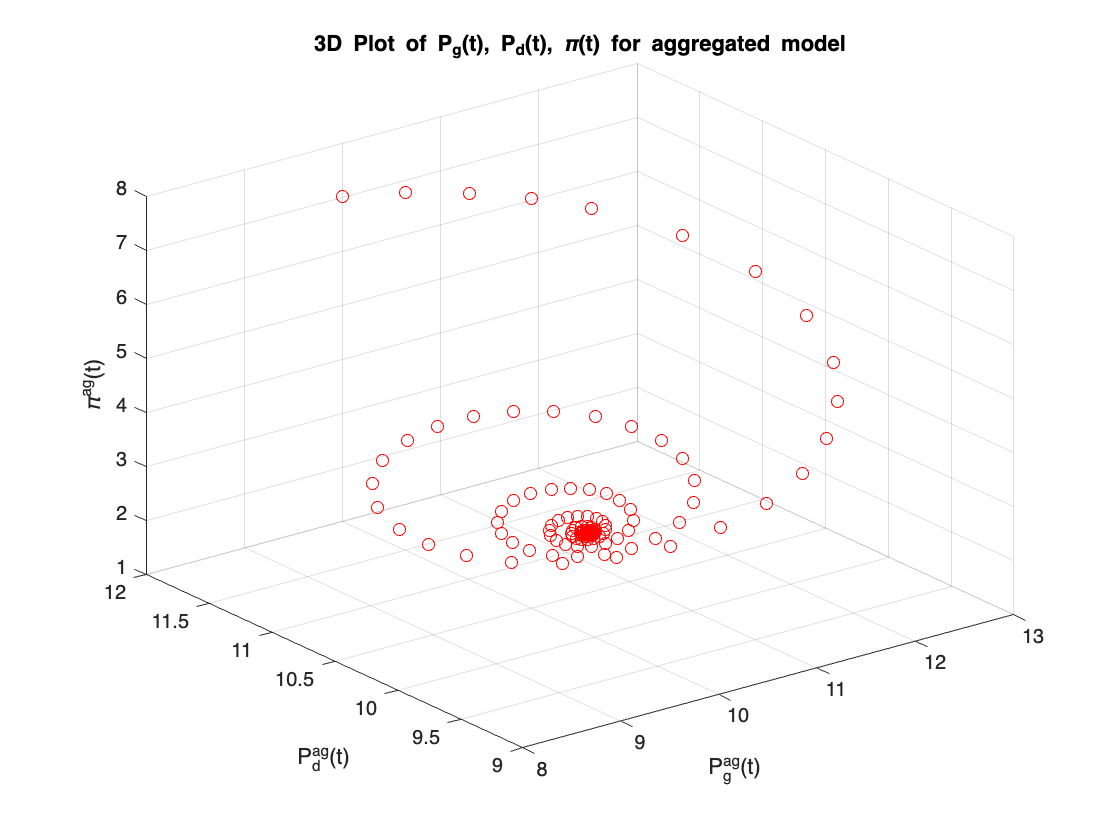


d = figure;
plot3(Pg_ag, Pd_ag, Pi_ag, 'ro');
xlabel('P_g^{ag}(t)');
ylabel('P_d^{ag}(t)');
zlabel('\pi^{ag}(t)');
title('3D Plot of P_g(t), P_d(t), \pi(t) for aggregated model');
grid on;


saveFigureIfNeeded(shouldSave, caseno, '3d-aggregated.png', d);

Figure not saved.


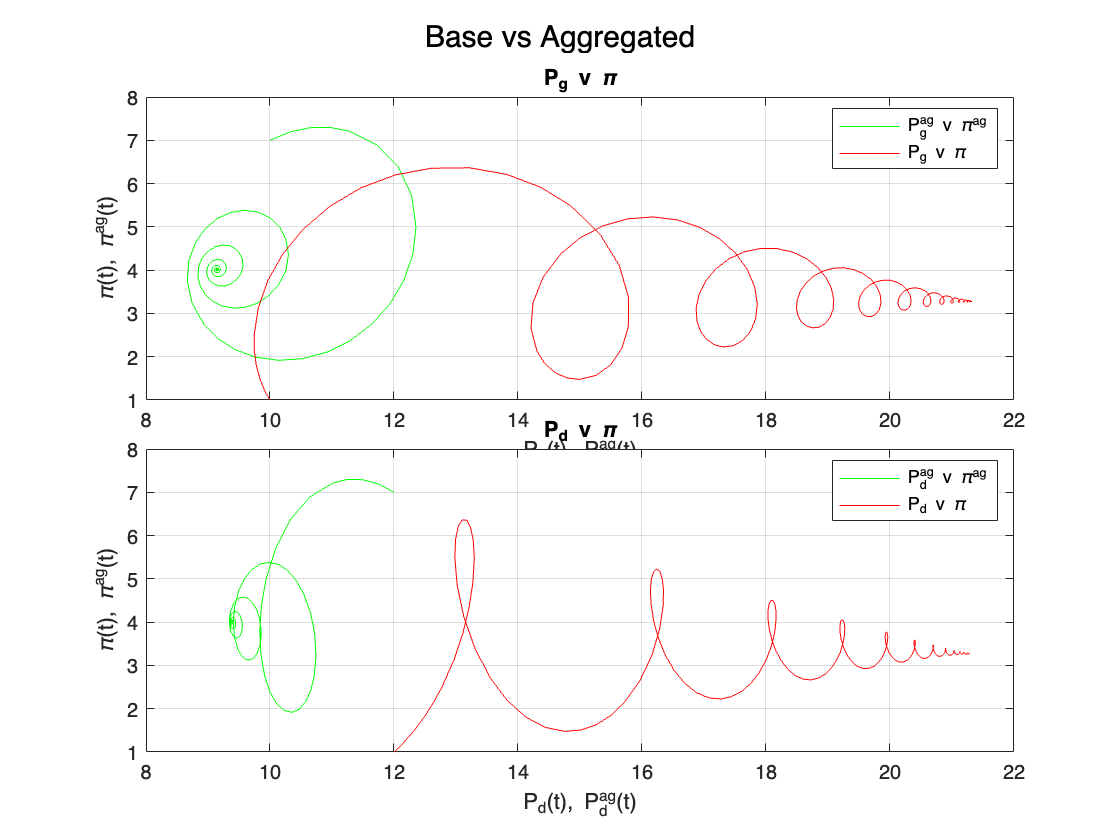


e = figure;
subplot(4, 1, [1,2]);
plot(Pg_ag, Pi_ag, 'g');
hold on;
plot(Pg, Pi, 'r');
xlabel('P_g(t), P_g^{ag}(t)');
ylabel('\pi(t), \pi^{ag}(t)');
title('P_g v \pi');
legend('P_g^{ag} v \pi^{ag}', 'P_g v \pi');
grid on;
hold off;

subplot(4, 1, [3,4]);
plot(Pd_ag, Pi_ag, 'g');
hold on;
plot(Pd, Pi, 'r');
xlabel('P_d(t), P_d^{ag}(t)');
ylabel('\pi(t), \pi^{ag}(t)');
title('P_d v \pi');
legend('P_d^{ag} v \pi^{ag}', 'P_d v \pi');
grid on;
hold off;

sgtitle('Base vs Aggregated');


saveFigureIfNeeded(shouldSave, caseno, 'base_v_aggregated.png', e);

Figure not saved.


## Root Locus

% Define parameters
syms thetav etav s;

% Define alpha and beta vectors
alphav = [0; 
         1/etav];
betav = [-1/(mu*etav); 
        -thetav/(mu*etav)];

A = [-a__g, 0, 0, tau__g;
      0, a__d, 0, -tau__d;
      betav(1), -betav(1), 0, -alphav(1);
      betav(2), -betav(2), 1, -alphav(2)];

In = eye(4);

% Define characteristic equation
alpha_s = det(s*In - A);

% Compute the polynomial coefficients
coeffs_alpha = coeffs(alpha_s, s, 'All');
coeffs_alpha = fliplr(coeffs_alpha); % Ensure the coefficients are in descending order

% Convert to function
alpha_func = matlabFunction(alpha_s, 'Vars', [s, etav, thetav]);


% Define k values
k = 1:1000;
nnk = 0.2 + (k-1)/20;
ttk = 0.5 + (k-1)/10;

% Preallocate arrays for roots
G_eta_roots = zeros(length(k), 4);
G_theta_roots = zeros(length(k), 4);

% Calculate roots for each k
for idx = 1:length(k)
    % Calculate G_eta roots
    alpha_eta = alpha_func(s, nnk(idx), theta);
    coeffs_eta = double(coeffs(alpha_eta, s, 'All'));
    G_eta_roots(idx, :) = roots(coeffs_eta);
    
    % Calculate G_theta roots
    alpha_theta = alpha_func(s, eta, ttk(idx));
    coeffs_theta = double(coeffs(alpha_theta, s, 'All'));
    G_theta_roots(idx, :) = roots(coeffs_theta);
end

% Swap columns after the specified index
swap_idx = 238;
G_eta_roots(swap_idx:end, :) = G_eta_roots(swap_idx:end, [2, 3, 1, 4]);


Plot root locus for parameter eta

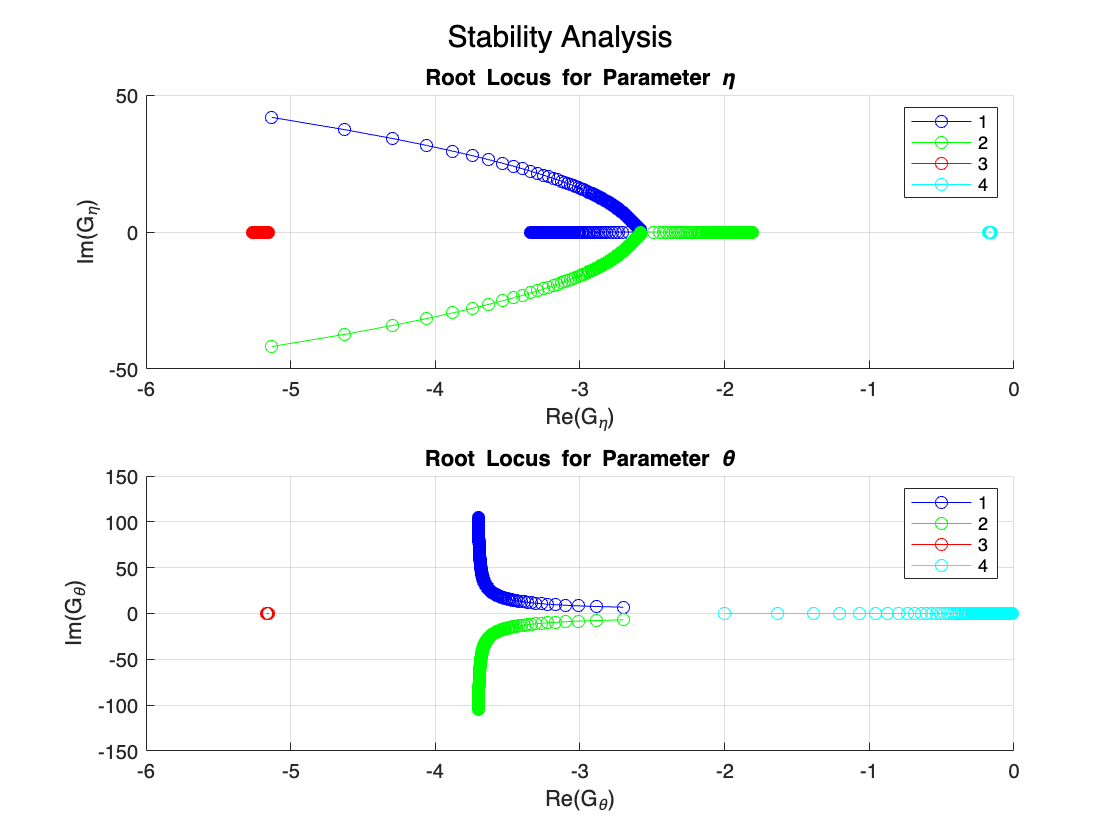

f = figure;
subplot(2, 1, 1);
hold on;
plot(real(G_eta_roots(:, 1)), imag(G_eta_roots(:, 1)), 'b-o');
plot(real(G_eta_roots(:, 2)), imag(G_eta_roots(:, 2)), 'g-o');
plot(real(G_eta_roots(:, 3)), imag(G_eta_roots(:, 3)), 'r-o');
plot(real(G_eta_roots(:, 4)), imag(G_eta_roots(:, 4)), 'c-o');
xlabel('Re(G_\eta)');
ylabel('Im(G_\eta)');
title('Root Locus for Parameter \eta');
grid on;
legend('1', '2', '3', '4');
hold off;

% Plot root locus for parameter theta
subplot(2, 1, 2);
hold on;
plot(real(G_theta_roots(:, 1)), imag(G_theta_roots(:, 1)), 'b-o');
plot(real(G_theta_roots(:, 2)), imag(G_theta_roots(:, 2)), 'g-o');
plot(real(G_theta_roots(:, 3)), imag(G_theta_roots(:, 3)), 'r-o');
plot(real(G_theta_roots(:, 4)), imag(G_theta_roots(:, 4)), 'c-o');
xlabel('Re(G_\theta)');
ylabel('Im(G_\theta)');
title('Root Locus for Parameter \theta');
legend('1', '2', '3', '4');
grid on;
hold off;
sgtitle('Stability Analysis');

saveFigureIfNeeded(shouldSave, caseno, 'stability-analysis.png', f);

Figure not saved.


## Time-decomposition

Create base variables

% Stack vectors
ag_ad = [-a_g a_d];
tau_g_tau_d = [tau_g tau_d];
b = [-b_g b_d]';
c = [cm; cn];

% Create diagonal matrices
A = diag(ag_ad);
T = diag(tau_g_tau_d);

% Calculate other parameters
E = c * c';
I = eye(length(c));
tau = c' * (T \ c);
beta_td = c' * (T \ b);

% Define A0 matrix
A0 = (I - (tau \ E')/T) * A - (theta * tau) \ E;

Define system variables

% Define other matrices
Ass = T \ A0;
Bss = T \ (b - (tau \ beta_td) * c);

% Define initial conditions
P0 = [Pg_ic Pd_ic]';
u = 1;

% Define state-space model
C = eye(size(A));
D = zeros(size(Bss));
sys = ss(Ass, Bss, C, D);

% Вибір Q - позитивно визначеної симетричної матриці
Q = eye(size(A));

% Розв'язання рівняння Ляпунова для знаходження P
P = lyap(A', Q);

% Перевірка, чи є P позитивно визначеною
eigP = eig(P);
if all(eigP > 0)
    disp('Матриця P є позитивно визначеною.');
else
    disp('Матриця P не є позитивно визначеною.');
end

Матриця P є позитивно визначеною.


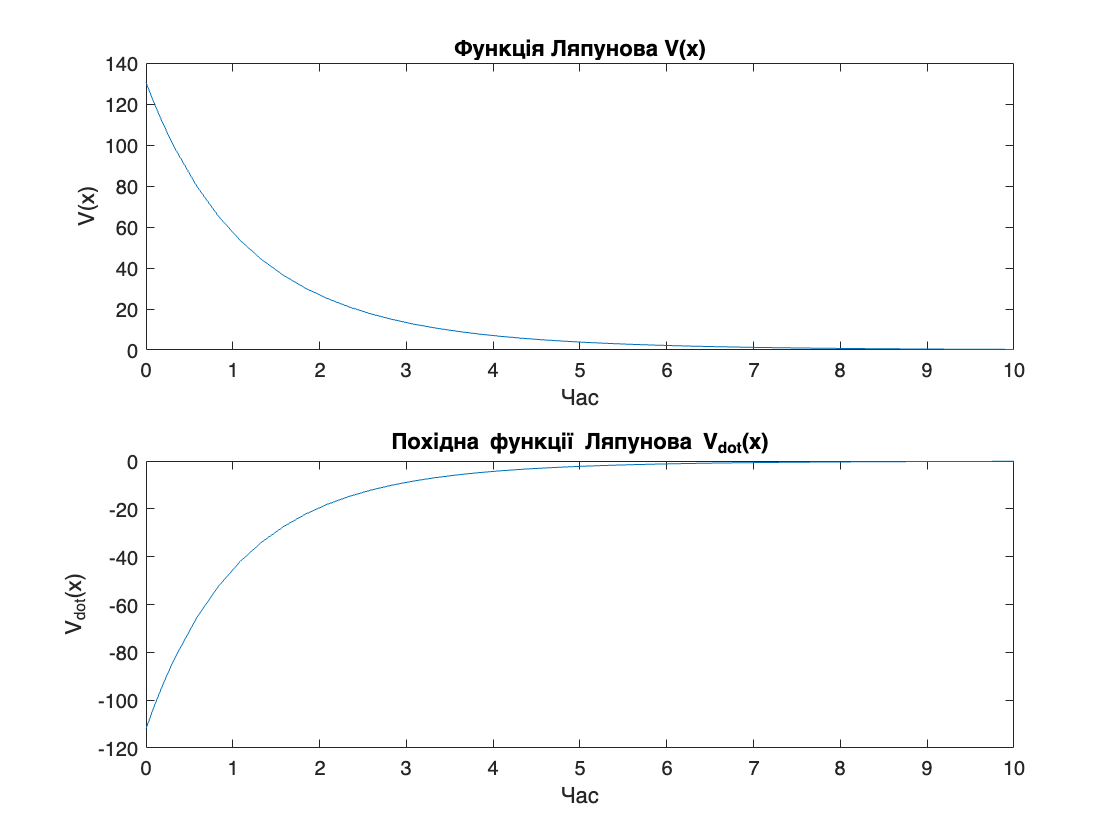


% Перевірка, чи є похідна функції Ляпунова від'ємною на траєкторіях системи
% Вибір початкових умов
x0 = P0;

% Моделювання системи
[t, x] = ode45(@(t, x) A*x, [0 10], x0);

% Обчислення V(x) та похідної V_dot(x)
V = zeros(length(t), 1);
V_dot = zeros(length(t), 1);
for i = 1:length(t)
    V(i) = x(i, :) * P * x(i, :)';
    V_dot(i) = -x(i, :) * Q * x(i, :)';
end

% Відображення результатів
figure;
subplot(2, 1, 1);
plot(t, V);
xlabel('Час');
ylabel('V(x)');
title('Функція Ляпунова V(x)');

subplot(2, 1, 2);
plot(t, V_dot);
xlabel('Час');
ylabel('V_{dot}(x)');
title('Похідна функції Ляпунова V_{dot}(x)');


% Аналіз результатів
if all(V_dot < 0)
    disp('Система є стійкою за Ляпуновим.');
else
    disp('Система не є стійкою за Ляпуновим.');
end

Система є стійкою за Ляпуновим.


Simulate the system using state-space representation

[~, td_span, X] = lsim(sys, u * ones(length(td_span), 1), td_span, P0);

Pg_extracted = X(:, 1:m);
Pd_extracted = X(:, m + 1:m + n);

% Extract Solutions
Pg4 = sum(Pg_extracted , 2);
Pd4 = sum(Pd_extracted , 2);
P4 = X';

% Calculate Pi4
Pi4 = (-tau \ (c' * (T \ (A * P4)) + beta_td) - (theta * tau) \ (Pg4 - Pd4)')';

Plot results

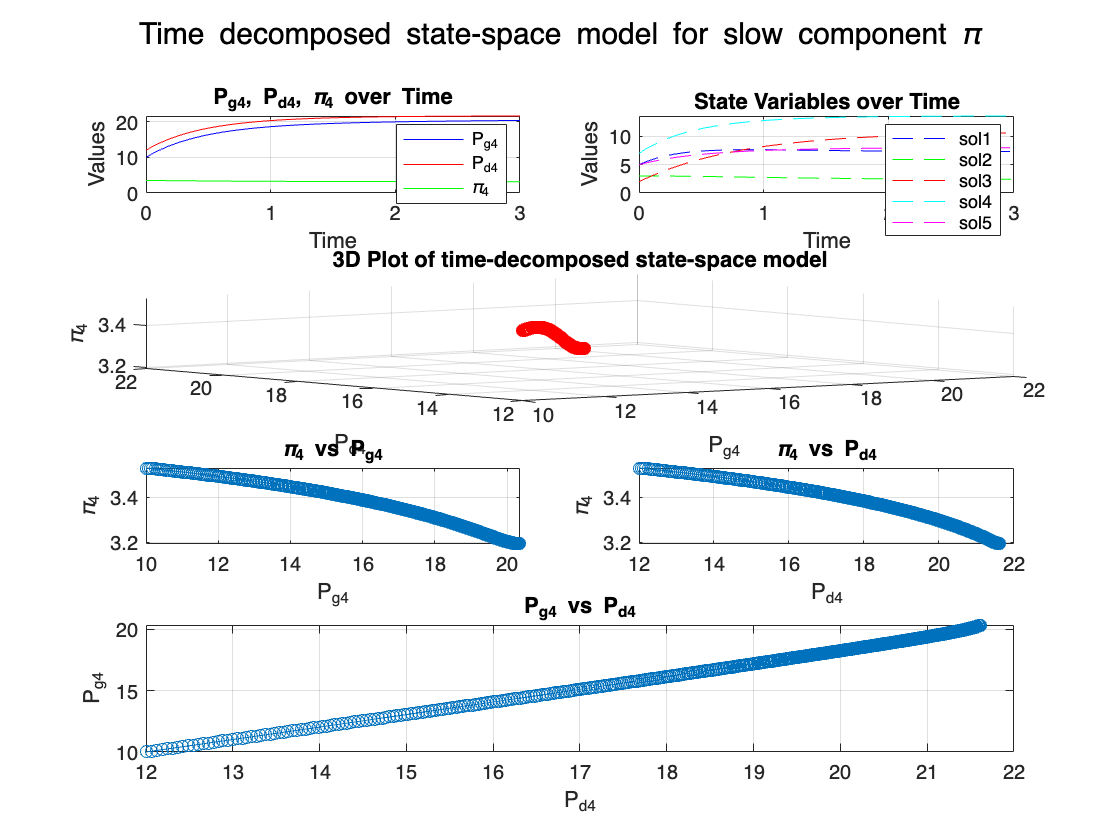

g = figure;
subplot(4, 2, 1);
plot(td_span, Pg4, 'b', 'DisplayName', 'P_{g4}');
hold on;
plot(td_span, Pd4, 'r', 'DisplayName', 'P_{d4}');
plot(td_span, Pi4, 'g', 'DisplayName', '\pi_4');
xlabel('Time');
ylabel('Values');
legend;
title('P_{g4}, P_{d4}, \pi_4 over Time');
grid on;

subplot(4, 2, 2);
plot(td_span, X(:, 1), 'b--', 'DisplayName', 'sol1');
hold on;
plot(td_span, X(:, 2), 'g--', 'DisplayName', 'sol2');
plot(td_span, X(:, 3), 'r--', 'DisplayName', 'sol3');
plot(td_span, X(:, 4), 'c--', 'DisplayName', 'sol4');
plot(td_span, X(:, 5), 'm--', 'DisplayName', 'sol5');
xlabel('Time');
ylabel('Values');
legend;
title('State Variables over Time');
grid on;

subplot(4, 2, [3, 4]);
plot3(Pg4, Pd4, Pi4, 'ro', 'DisplayName', '3D Plot');
xlabel('P_{g4}');
ylabel('P_{d4}');
zlabel('\pi_4');
title('3D Plot of time-decomposed state-space model');
grid on;

% Plot Pi4 vs Pg4
subplot(4, 2, 5);
plot(Pg4, Pi4, 'o-');
xlabel('P_{g4}');
ylabel('\pi_4');
title('\pi_4 vs P_{g4}');
grid on;

% Plot Pi4 vs Pd4
subplot(4, 2, 6);
plot(Pd4, Pi4, 'o-');
xlabel('P_{d4}');
ylabel('\pi_4');
title('\pi_4 vs P_{d4}');
grid on;

% Plot Pg4 vs Pd4
subplot(4, 2, [7, 8]);
plot(Pd4, Pg4, 'o-');
xlabel('P_{d4}');
ylabel('P_{g4}');
title('P_{g4} vs P_{d4}');
grid on;

sgtitle("Time decomposed state-space model for slow component \pi");


saveFigureIfNeeded(shouldSave, caseno, 'time-decomposed_state-space.png', g);

Figure not saved.


Solve ODE

time_decomposed_initial_conditions = [Pg_ic Pd_ic x10 x20];
[t, X] = ode45(@(t, X) time_decomposed_system_of_equations(t, X, tau_g_tau_d, a_g, b_g, a_d, b_d, tau, c, T, A, alpha, beta, beta_td, theta), t_span, time_decomposed_initial_conditions);

% Extract Solutions
Pg_extracted = X(:, 1:m);
Pd_extracted = X(:, m + 1:m + n);
pi_extracted = X(:, m + n + 1);

% Compute Pg and Pd
Pg = sum(Pg_extracted , 2);
Pd = sum(Pd_extracted , 2);
% Pi = pi_extracted;

Calculating f_pi_t

f_pi_t = zeros(size(t));
for k = 1:length(t)
    p = zeros(m+n, 1);
    for i=1:m
        p(i) = Pg_extracted(k, i);
    end
    for j=1:n
        p(m + j) = Pd_extracted(k, j);
    end
    % p = [Pg1(k); Pg2(k); Pg3(k); Pd1(k); Pd2(k)];
    f_pi_t(k) = compute_f_pi_p(p, tau, c, T, A, beta_td, theta);
end

Plot the results

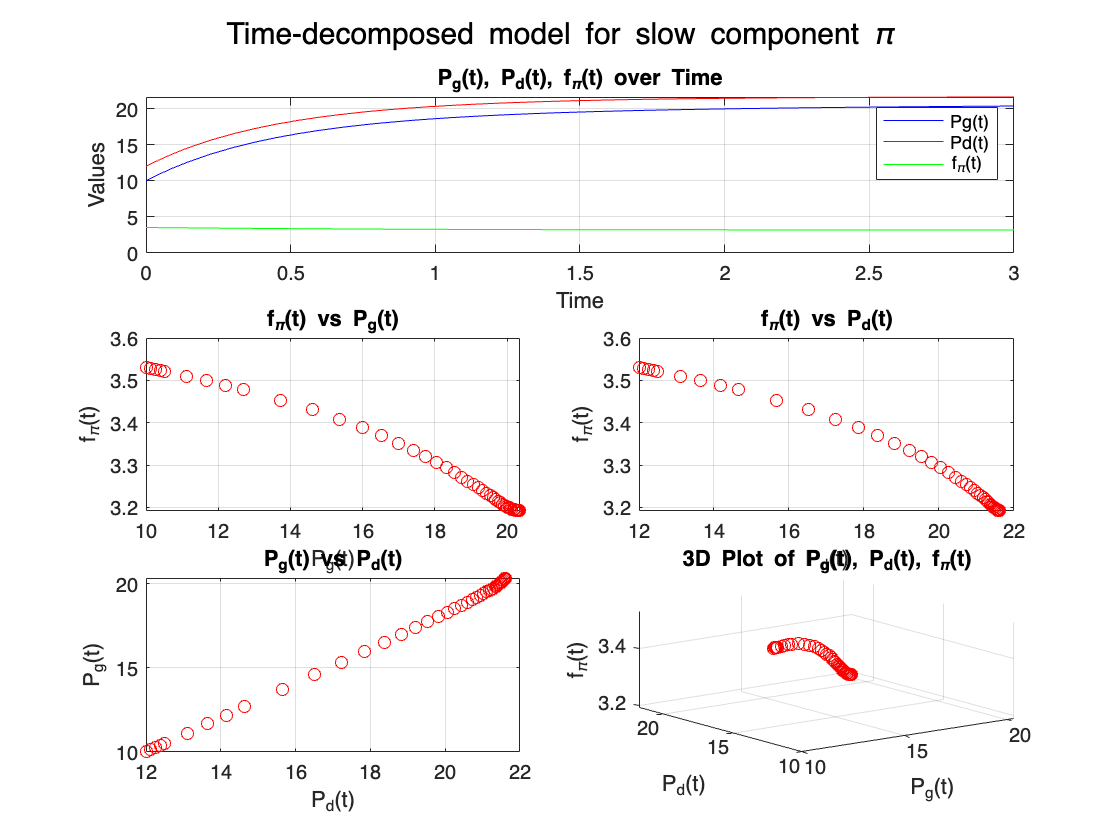

h = figure;

% Plot Pg, Pd, and f_pi_t over time
subplot(3, 1, 1);
plot(t, Pg, 'b', 'DisplayName', 'Pg(t)');
hold on;
plot(t, Pd, 'r', 'DisplayName', 'Pd(t)');
plot(t, f_pi_t, 'g', 'DisplayName', 'f_\pi(t)');
xlabel('Time');
ylabel('Values');
legend;
title('P_g(t), P_d(t), f_\pi(t) over Time');
grid on;

% Plot f_pi_t vs Pg
subplot(3, 2, 3);
plot(Pg, f_pi_t, 'ro');
xlabel('P_g(t)');
ylabel('f_\pi(t)');
title('f_\pi(t) vs P_g(t)');
grid on;

% Plot f_pi_t vs Pd
subplot(3, 2, 4);
plot(Pd, f_pi_t, 'ro');
xlabel('P_d(t)');
ylabel('f_\pi(t)');
title('f_\pi(t) vs P_d(t)');
grid on;

% Plot Pg vs Pd
subplot(3, 2, 5);
plot(Pd, Pg, 'ro');
xlabel('P_d(t)');
ylabel('P_g(t)');
title('P_g(t) vs P_d(t)');
grid on;

% 3D plot
subplot(3, 2, 6);
plot3(Pg, Pd, f_pi_t, 'ro');
xlabel('P_g(t)');
ylabel('P_d(t)');
zlabel('f_\pi(t)');
title('3D Plot of P_g(t), P_d(t), f_\pi(t)');
grid on;

sgtitle('Time-decomposed model for slow component \pi');


saveFigureIfNeeded(shouldSave, caseno, 'time-decomposed_slow_analysis.png', h);

Figure not saved.


## Fast movements

% Scalars
mu = 0.1;
theta_ = 1.9;
eta = 0.5;
theta = theta_ + eta;

% Vectors alpha and beta
alpha = [theta*tau, 1/eta];
beta = [-1/(mu*eta), -theta/(mu*eta)];

Solve ODE

[t, X] = ode45(@(t, X) basic_system_of_equations(t, X, tau_g, a_g, b_g, tau_d, a_d, b_d, alpha, beta), t_span, initial_conditions);

% Extract solutions
Pg_extracted = X(:, 1:m);
Pd_extracted = X(:, m + 1:m + n);
pi_extracted = X(:, m + n + 1);

% Compute Pg and Pd
Pg = sum(Pg_extracted , 2);
Pd = sum(Pd_extracted , 2);
Pi = pi_extracted;

Plot figures

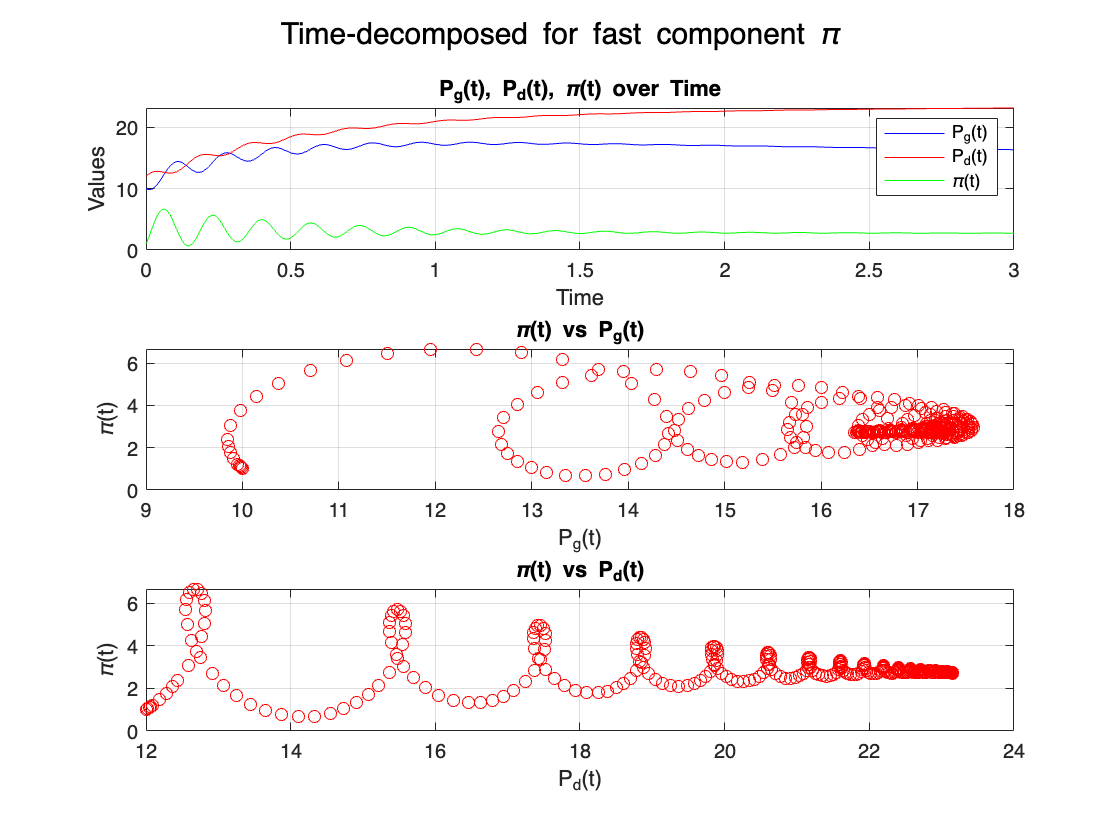

i = figure;

subplot(3, 1, 1);
plot(t, Pg, 'b', 'DisplayName', 'P_g(t)');
hold on;
plot(t, Pd, 'r', 'DisplayName', 'P_d(t)');
plot(t, Pi, 'g', 'DisplayName', '\pi(t)');
xlabel('Time');
ylabel('Values');
legend;
title('P_g(t), P_d(t), \pi(t) over Time');
grid on;

subplot(3, 1, 2);
plot(Pg, Pi, 'ro');
xlabel('P_g(t)');
ylabel('\pi(t)');
title('\pi(t) vs P_g(t)');
grid on;

subplot(3, 1, 3);
plot(Pd, Pi, 'ro');
xlabel('P_d(t)');
ylabel('\pi(t)');
title('\pi(t) vs P_d(t)');
grid on;

sgtitle("Time-decomposed for fast component \pi");

saveFigureIfNeeded(shouldSave, caseno, 'time-decomposed_fast_analysis.png', i);

Figure not saved.


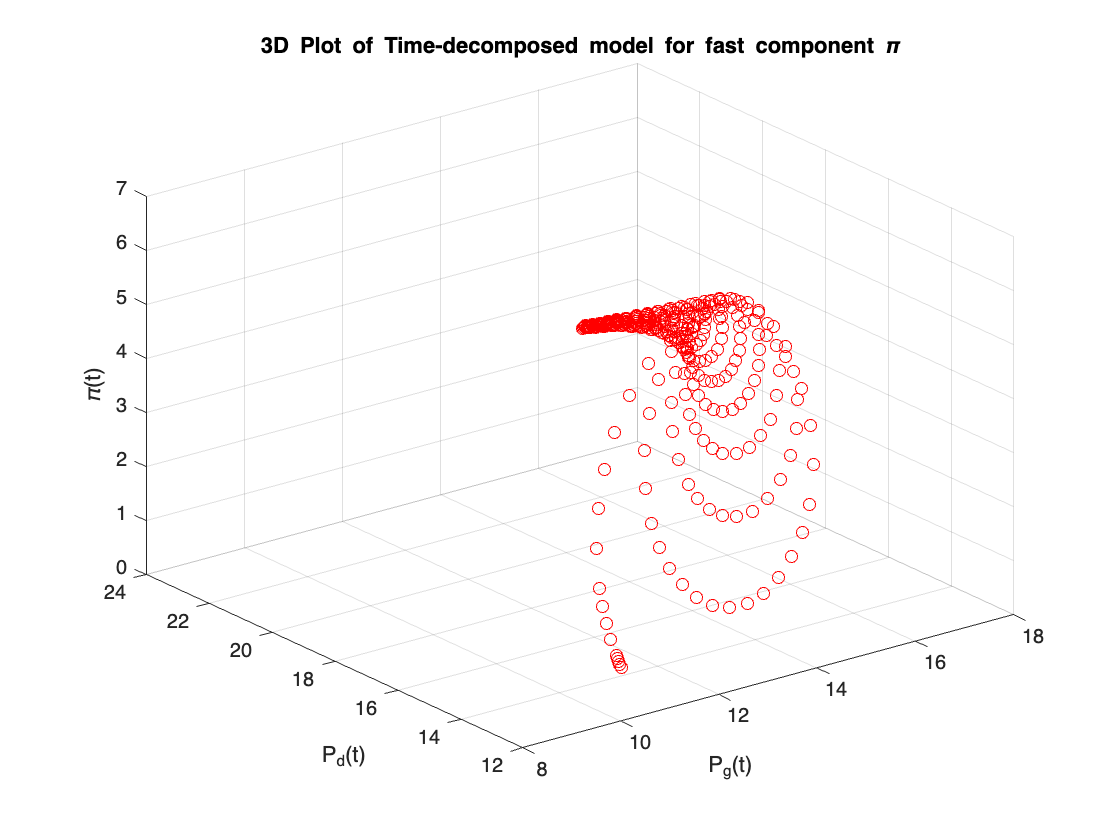


j = figure;
plot3(Pg, Pd, Pi, 'ro');
xlabel('P_g(t)');
ylabel('P_d(t)');
zlabel('\pi(t)');
title('3D Plot of Time-decomposed model for fast component \pi');
grid on;

saveFigureIfNeeded(shouldSave, caseno, '3d-time-decomposed_fast.png', j);

Figure not saved.
